F= phi

% TD1: Excersice 1
K = 1:10;
S = [0 0.52 0.9 1.2 1.4 1.55 1.67 1.73 1.82 1.86];
E = ones(1, 10); E(1)=0; %modification

N=size(K,2)

N = 10

F = zeros(N-1, 2);
F(:,1) = -S(1:N-1);  % -s(k-1)
F(:,2) =  E(2:N);    %  e(k)

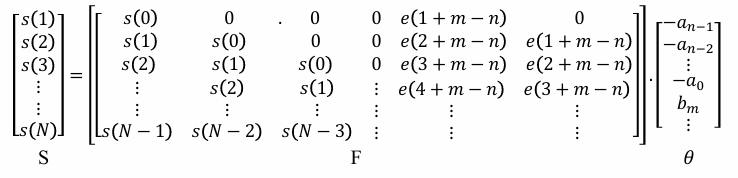

%theta_LS=Phi/E; %Phi/Y;

% Corresponding output vector S_out = s(k) for k=2..N
S_out = S(2:N).';
theta = F \ S_out;      % [a; b0]
a_est  = theta(1)

a_est = -0.7377

b0_est = theta(2)

b0_est = 0.5211

## Excersice 2

% TD1: Excersice 2
K = 1:5;
S = [0,0.2, 0.55, 0.77, 0.74];
E = [1,0.8, 0.45, 0.23, 0.26];

N=size(K,2)

N = 5

n_params=4; %b1,b0,a1,a0
Phi = zeros(N-1, n_params);
Phi(:,1)= S(1:N-1);
Phi(2:N-1,2)=S(1:N-2);
%m=2,n=2
Phi(:,3) =  E(2:N); 
Phi(2:N-1,4) =  E(2:N-1); 
Phi

Phi =          0         0    0.8000         0
    0.2000         0    0.4500    0.8000
    0.5500    0.2000    0.2300    0.4500
    0.7700    0.5500    0.2600    0.2300


S_out = S(2:N).';
theta = Phi \ S_out;      % [a; b0]
theta

theta =     1.4948
   -0.9379
    0.2500
    0.1732
